# Color Differences

Github Link: https://github.com/pratheepkumar1/Principles-of-Color-Science

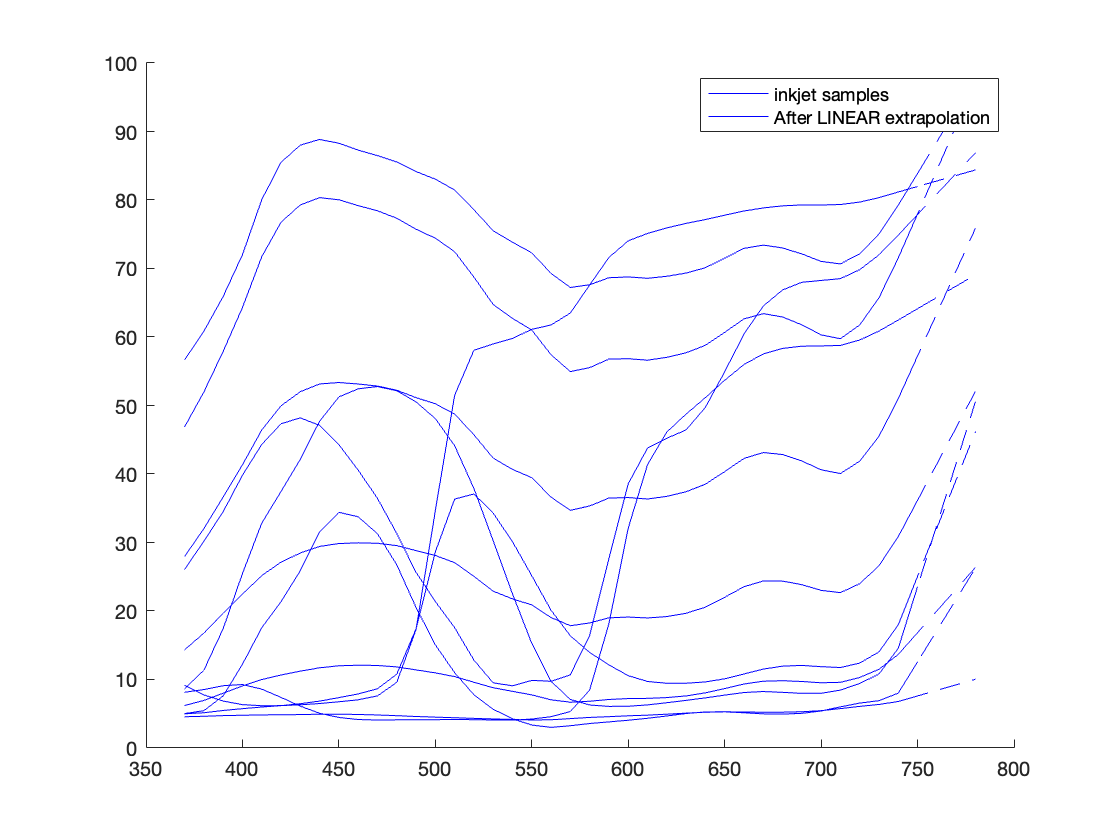

% Reading the Dataset
clear;
warning('off','all');
inkjetColorChecker_dataset = readtable("InkjetColorChecker.xlsx");
source_dataset = readtable("Illuminant Data.xlsx");
xyz_std_obs_two_deg_dataset = readtable("StdObsFuncs.xlsx",Sheet="2-degree");
patch_dataset = readtable("MacbethColorChecker.xlsx");
labels_patch = {'13','14','15','16','17','18','19','20','21','22','23','24'};

d_lambda = 5;
wavelength_info = 380:5:780;


%Interpolating and extrapolating the dataset (as needed)
xyz_std_obs_two_deg = interp1(xyz_std_obs_two_deg_dataset{:,1},...
    xyz_std_obs_two_deg_dataset{:,2:end},wavelength_info,"linear","extrap");
source_A = interp1(source_dataset{:,1},source_dataset.A,...
    wavelength_info,"linear","extrap");
source_D65 = interp1(source_dataset{:,1},source_dataset.D65,...
    wavelength_info,"linear","extrap");
patch_macbeth_ref = interp1(patch_dataset{2:end,1},patch_dataset{2:end,2:end},...
    wavelength_info,"linear","extrap");
inkjetColorChecker = interp1(inkjetColorChecker_dataset{2:end,1},....
    inkjetColorChecker_dataset{2:end,2:end},wavelength_info,"linear","extrap");

inkjetColorChecker_norm = normalize(inkjetColorChecker,'range');



figure;
hold on
plot(inkjetColorChecker_dataset{2:end,1},inkjetColorChecker_dataset{2:end,2:end},...
    'Color','blue');
plot(wavelength_info,inkjetColorChecker(:,1:end),'--','Color','blue');
% plot(wavelength_info,inkjetColorChecker_alt(:,1),'--','Color','red');
legend('inkjet samples','After LINEAR extrapolation');
hold off

The provided dataset for inkjet color patches is available from 360nm to 750nm with 10nm difference. Whereas, Macbeth color check dataset is available from 380nm to 780nm with 5nm difference. So, the inkjet color patches (batch) data set is interpolated and extrapolated to match Macbeth patches (standard) wavelength range. For extrapolation of the dataset, there are multiple options to extrapolate such as linear, nearest, cubic. Out of this, linear extrapolation provided better dataset for the missing wavelength in have has a curve below. Above figure graphically shows the difference between before and after extrapolation of inkjet color patches.

% White point value of Source A and Source D65 for 2 degree observer
wp_A_two_deg_source = calcTristimulusSource(xyz_std_obs_two_deg,source_A,d_lambda);
wp_D65_two_deg_source = calcTristimulusSource(xyz_std_obs_two_deg,source_D65,d_lambda);

## Question 1

Compute and make tables of CIELAB values of the inkjet-printed patches from the spectral reflectance data for Illuminants A and D65. 

*Note: Calculation for CIELAB values as written as separate function script file (calXYZtoCIELAB.m)*

% Tristimulus value for all patches in InkjetColorChecker in A and D65 Source ...
% for 2 degree observer
tristimulus_XYZ_A_two_deg_inkjet = calcTristimulus(xyz_std_obs_two_deg,...
    source_A,inkjetColorChecker_norm,d_lambda);
tristimulus_XYZ_D65_two_deg_inkjet = calcTristimulus(xyz_std_obs_two_deg,...
    source_D65,inkjetColorChecker_norm,d_lambda);


%Calculate L_star, a_star, b_star, C_star for all patches in InkjetColorChecker...
% in A and D65 Source 
[L_A_inkjet, a_A_inkjet, b_A_inkjet, C_A_inkjet] = calcXYZtoCIELAB...
    (tristimulus_XYZ_A_two_deg_inkjet,wp_A_two_deg_source);
[L_D65_inkjet, a_D65_inkjet, b_D65_inkjet, C_D65_inkjet] = calcXYZtoCIELAB...
    (tristimulus_XYZ_D65_two_deg_inkjet,wp_D65_two_deg_source);

CIELAB_A_inkjet = [L_A_inkjet; a_A_inkjet; b_A_inkjet; C_A_inkjet];
CIELAB_D65_inkjet = [L_D65_inkjet; a_D65_inkjet; b_D65_inkjet; C_D65_inkjet];


table_CIELAB_A_inkjet = createTableCIELAB(CIELAB_A_inkjet)

table_CIELAB_A_inkjet = 12×4 table
      L          a          b         C   
    ______    _______    _______    ______

    31.521     10.755    -103.01    103.57
    64.638    -62.448      34.56    71.373
    52.235     69.988     75.404    102.88
    89.347     10.034     97.399    97.914
    50.128     60.535    -29.754    67.452
    50.443    -68.419    -79.254     104.7
     60.41    -12.017    -44.887    46.467
    49.292    -15.769    -53.489    55.765
    46.562    -11.836    -45.944    47.444
     39.57    -11.281    -44.829    46.227
    29.109    -8.3734     -48.03    48.754
    31.231     34.137    -17.094    38.178


table_CIELAB_D65_inkjet = createTableCIELAB(CIELAB_D65_inkjet)

table_CIELAB_D65_inkjet = 12×4 table
      L          a          b         C   
    ______    _______    _______    ______

    39.247      50.54    -92.144    105.09
    69.243    -78.112     52.568    94.154
    42.611     72.119     55.585    91.054
    86.529    -4.9653     105.69     105.8
    44.694     74.171    -42.745    85.606
    60.698    -29.843     -61.35    68.223
    64.024    -1.1775    -39.642    39.659
    54.007    -1.5462    -46.352    46.378
    50.525    -2.0795     -39.66    39.715
    43.552    -2.4432    -38.281    38.359
    33.385     1.5419    -41.047    41.076
    28.477     39.365    -23.428    45.809


## Question 2 (Prerequisite Calculations)

Calculating CIELAB values for Macbeth refpatches

% Tristimulus value for all patches in InkjetColorChecker in A and D65 Source...
% for 2 degree observer
tristimulus_XYZ_A_two_deg_macbeth_ref = calcTristimulus(xyz_std_obs_two_deg,...
    source_A,patch_macbeth_ref,d_lambda);
tristimulus_XYZ_D65_two_deg_macbeth_ref = calcTristimulus(xyz_std_obs_two_deg,...
    source_D65,patch_macbeth_ref,d_lambda);

%Calculate L_star, a_star, b_star, C_star for all patches in InkjetColorChecker...
% in A and D65 Source 
[L_A_macbeth_ref, a_A_macbeth_ref, b_A_macbeth_ref, C_A_macbeth_ref] = ...
    calcXYZtoCIELAB(tristimulus_XYZ_A_two_deg_macbeth_ref,wp_A_two_deg_source);
[L_D65_macbeth_ref, a_D65_macbeth_ref, b_D65_macbeth_ref, C_D65_macbeth_ref] = ...
    calcXYZtoCIELAB(tristimulus_XYZ_D65_two_deg_macbeth_ref,wp_D65_two_deg_source);

CIELAB_A_macbeth_ref = [L_A_macbeth_ref; a_A_macbeth_ref; b_A_macbeth_ref;...
    C_A_macbeth_ref];
CIELAB_D65_macbeth_ref = [L_D65_macbeth_ref; a_D65_macbeth_ref; b_D65_macbeth_ref;...
    C_D65_macbeth_ref];

table_CIELAB_A_macbeth_ref = createTableCIELAB(CIELAB_A_macbeth_ref)

table_CIELAB_A_macbeth_ref = 24×4 table
      L          a           b         C   
    ______    ________    _______    ______

    39.544      16.837      19.28    25.597
    68.578      20.731     20.354    29.053
    48.985     -9.7193    -23.384    25.323
    42.306     -11.323     20.017    22.997
    55.867      6.6138    -24.249    25.135
    68.402      -30.41    -5.5113    30.905
    66.496       33.52     65.415    73.503
    38.562    -0.10231    -44.026    44.026
    56.583      47.727     25.407    54.068
    31.744      18.784    -17.656    25.779
    71.856     -17.005     52.138    54.841
    75.763      20.878     70.171    73.211
      27.1      2.5465    -54.065    54.125
    53.496     -36.187     27.189    45.264
    47.852      56.731     37.689    68.109
    84.411      9.8062     77.271     77.89


table_CIELAB_D65_macbeth_ref = createTableCIELAB(CIELAB_D65_macbeth_ref)

table_CIELAB_D65_macbeth_ref = 24×4 table
      L          a          b         C   
    ______    _______    _______    ______

    37.304     13.692     15.564    20.729
      66.2     14.467      17.74    22.891
    50.781    -1.4728    -21.266    21.317
     42.74    -16.298     22.344    27.656
    56.468     11.518    -24.399    26.981
    71.371    -31.393     1.9816    31.455
    61.069     31.126     57.163    65.088
    40.828     15.397    -41.888    44.628
    50.952     45.921     15.086    48.335
    30.696     23.901    -22.073    32.534
    72.001    -27.183     58.033    64.084
    71.642     15.324     65.884    67.642
    29.986     24.609    -50.865    56.506
    55.655    -41.682     34.775    54.284
    40.937     52.848     25.607    58.725
    81.641    -1.5754     79.474     79.49


## Question 2

Calculate and make tables of ΔL*, Δa*, Δb*, ΔC*, ΔH*, ΔE*ab and ΔE*00 color differences *(Please put columns in this order to make grading easier!)* between the 12 corresponding patches on the inkjet-printed ColorChecker (sample set) and the real ColorChecker (reference set). You can calculate ΔE*00 with the provided m-file (it takes Lab arrays in 3xN orientation), but please write you own Matlab code for the other differences. Please make a two tables: one for the D65 data and one for the A data.

*Note: Calculation for color difference values as written as separate function below*


% Delta calculation for A
deltaL_A = deltaL(L_A_inkjet,L_A_macbeth_ref(:,13:24));

deltaa_A = deltaa(a_A_inkjet,a_A_macbeth_ref(:,13:24));

deltab_A = deltab(b_A_inkjet,b_A_macbeth_ref(:,13:24));

deltaC_A = deltaC(C_A_inkjet,C_A_macbeth_ref(:,13:24));

deltah_A = deltah(CIELAB_A_inkjet,CIELAB_A_macbeth_ref(:,13:24));

deltaH_A = deltaH(C_A_inkjet,C_A_macbeth_ref(:,13:24),deltah_A);

deltaEab_A = deltaEab(deltaL_A,deltaC_A,deltaH_A);

deltaE00_A = deltaE00(CIELAB_A_inkjet,CIELAB_A_macbeth_ref(:,13:24));

color_diff_A = [deltaL_A; deltaa_A; deltab_A; deltaC_A; deltaH_A; deltaEab_A; deltaE00_A];



% Delta calculation for D65

deltaL_D65 = deltaL(L_D65_inkjet,L_D65_macbeth_ref(:,13:24));

deltaa_D65 = deltaa(a_D65_inkjet,a_D65_macbeth_ref(:,13:24));

deltab_D65 = deltab(b_D65_inkjet,b_D65_macbeth_ref(:,13:24));

deltaC_D65 = deltaC(C_D65_inkjet,C_D65_macbeth_ref(:,13:24));

deltah_D65 = deltah(CIELAB_D65_inkjet,CIELAB_D65_macbeth_ref(:,13:24));

deltaH_D65 = deltaH(C_D65_inkjet,C_D65_macbeth_ref(:,13:24),deltah_D65);

deltaEab_D65 = deltaEab(deltaL_D65,deltaC_D65,deltaH_D65);

deltaE00_D65 = deltaE00(CIELAB_D65_inkjet,CIELAB_D65_macbeth_ref(:,13:24));

color_diff_D65 = [deltaL_D65; deltaa_D65; deltab_D65; deltaC_D65;...
    deltaH_D65; deltaEab_D65; deltaE00_D65];

table_color_diff_A = createTableColorDiff(color_diff_A)

table_color_diff_A = 12×7 table
      ΔL         Δa         Δb         ΔC        ΔH        ΔEab      ΔE00 
    _______    _______    _______    ______    _______    ______    ______

     4.4215     8.2082    -48.948    49.448     4.2641    49.828    9.4239
     11.142    -26.261       7.37     26.11     7.8891    29.463    12.778
     4.3835     13.257     37.715     34.77     19.729    40.217    13.327
     4.9362    0.22828     20.128    20.024     2.0583    20.726    5.2751
     -5.427     12.438    -25.014    19.122    -20.366    28.458    11.744
     3.5493    -35.918    -43.609    56.463     1.9287    56.607    13.191
    -35.067    -12.059    -45.399    45.954     9.7311    58.618    34.198
    -31.683    -15.823    -53.612    55.631     5.4526

table_color_diff_D65 = createTableColorDiff(color_diff_D65)

table_color_diff_D65 = 12×7 table
      ΔL          Δa         Δb         ΔC        ΔH        ΔEab      ΔE00 
    _______    ________    _______    ______    _______    ______    ______

     9.2605      25.931    -41.279    48.589     3.9349     49.62    12.212
     13.588      -36.43     17.794     39.87     7.3555    42.759    15.044
     1.6731      19.271     29.978    32.329     14.996    35.677     10.97
     4.8878     -3.3898     26.213    26.314     2.4875     26.88    6.1798
     -6.306      24.746    -27.706    33.944    -15.092     37.68    12.105
     9.0114     -5.1164    -35.367    32.355     15.171    36.854    14.122
     -31.44    -0.82041     -40.42    38.803     11.347    51.215    31.073
    -26.945      -1.688    -46.485    46.18

## Question 3

Discuss your results, including what you observe between the two ΔE metrics and what you lose by using a ΔE value as opposed to its components (ΔL*, Δa*, Δb*, ΔC*, ΔH*).

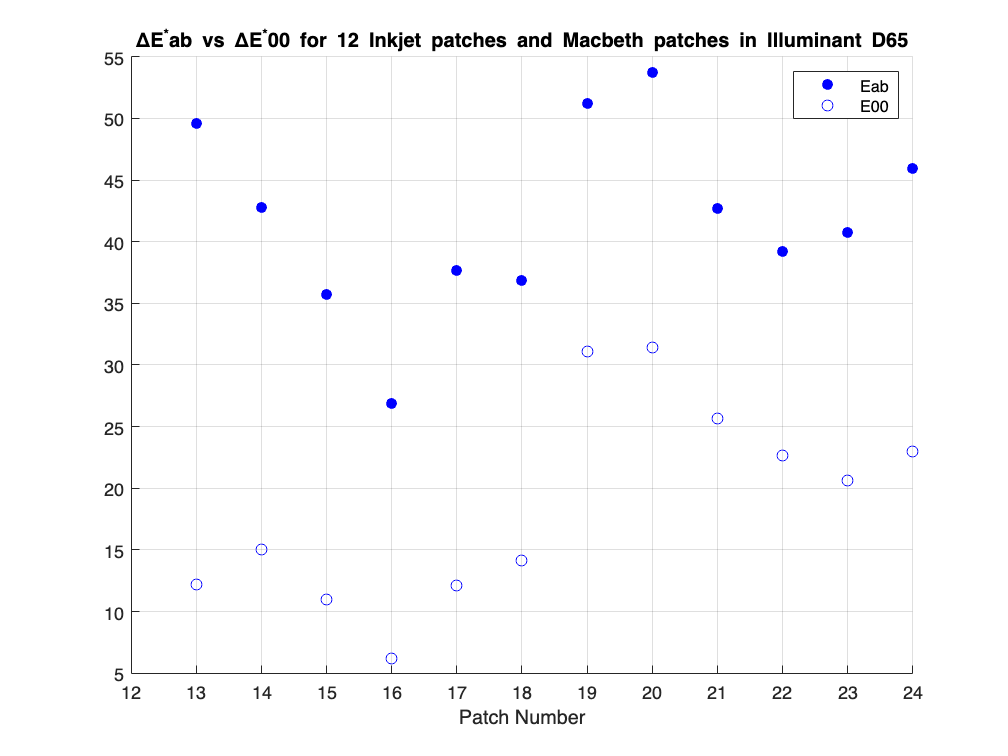

figure;
x_value = [13,14,15,16,17,18,19,20,21,22,23,24];
hold on
scatter(x_value,deltaEab_D65','filled','blue');
scatter(x_value,deltaE00_D65',"MarkerEdgeColor",'blue');
title('ΔE^{*}ab vs ΔE^{*}00 for 12 Inkjet patches and Macbeth patches in Illuminant D65');
xlabel("Patch Number");
xticks(12:1:24)
grid on
legend('Eab','E00');
hold off

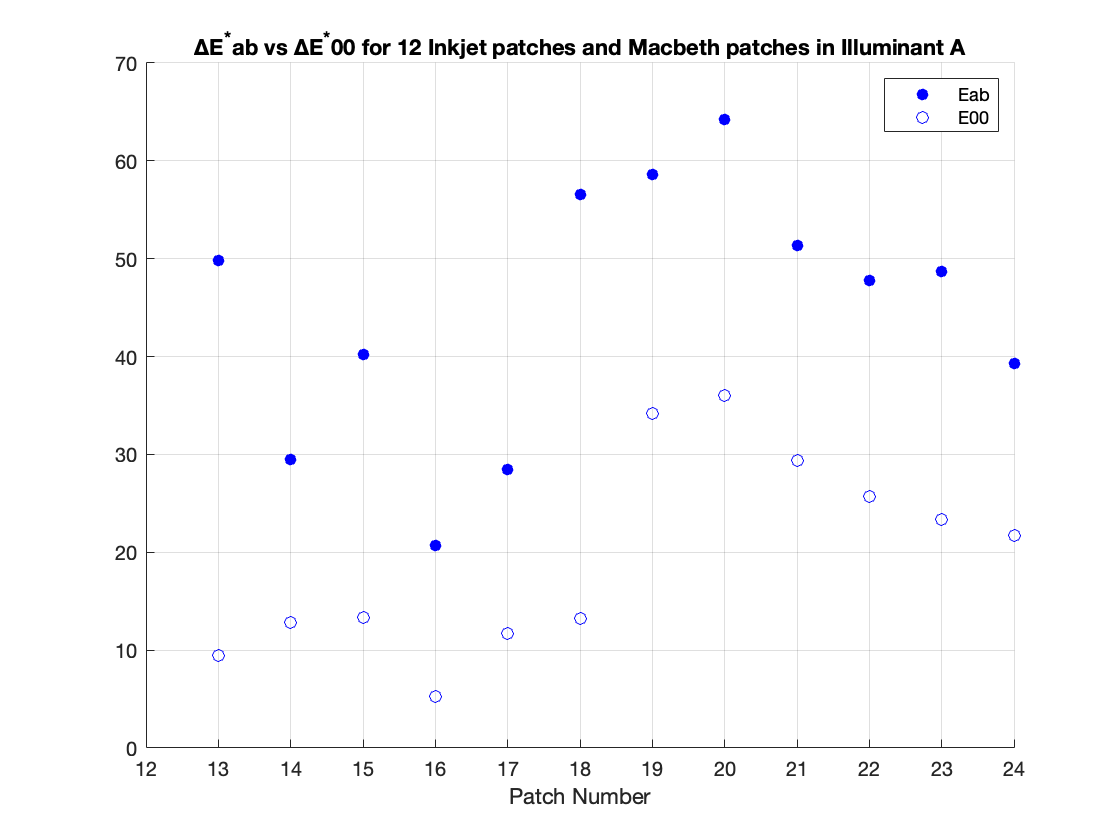

figure;
hold on
x_value = [13,14,15,16,17,18,19,20,21,22,23,24];
scatter(x_value,deltaEab_A','filled','blue');
scatter(x_value,deltaE00_A',"MarkerEdgeColor",'blue');
title('ΔE^{*}ab vs ΔE^{*}00 for 12 Inkjet patches and Macbeth patches in Illuminant A');
xlabel("Patch Number");
xlim([12 24]);
xticks(12:1:24)
legend('Eab','E00');
grid on
hold off

mean_deltaEab_A = mean(deltaEab_A);
mean_deltaEab_D65 = mean(deltaEab_D65);
mean_deltaE00_A = mean(deltaE00_A);
mean_deltaE00_D65 = mean(deltaE00_D65);
mean_deltaE = [mean_deltaEab_A;mean_deltaEab_D65;mean_deltaE00_A;mean_deltaE00_D65];

min_deltaEab_A = min(deltaEab_A);
min_deltaEab_D65 = min(deltaEab_D65);
min_deltaE00_A = min(deltaE00_A);
min_deltaE00_D65 = min(deltaE00_D65);
min_deltaE = [min_deltaEab_A;min_deltaEab_D65;min_deltaE00_A;min_deltaE00_D65];

max_deltaEab_A = max(deltaEab_A);
max_deltaEab_D65 = max(deltaEab_D65);
max_deltaE00_A = max(deltaE00_A);
max_deltaE00_D65 = max(deltaE00_D65);
max_deltaE = [max_deltaEab_A;max_deltaEab_D65;max_deltaE00_A;max_deltaE00_D65];

std_deltaEab_A = std(deltaEab_A);
std_deltaEab_D65 = std(deltaEab_D65);
std_deltaE00_A = std(deltaE00_A);
std_deltaE00_D65 = std(deltaE00_D65);
std_deltaE = [std_deltaEab_A;std_deltaEab_D65;std_deltaE00_A;std_deltaE00_D65];


Color_Difference_Summary = table(mean_deltaE,min_deltaE,max_deltaE,std_deltaE, 'VariableNames', {'Mean','Min','Max','Std'}, 'RowNames', {'ΔEab_A', 'ΔEab_D65','ΔE00_A','ΔE00_D65'})

Color_Difference_Summary = 4×4 table
                 Mean      Min       Max       Std  
                ______    ______    ______    ______

    ΔEab_A      44.611    20.726    64.253    13.259
    ΔEab_D65    41.918     26.88    53.756    7.5102
    ΔE00_A      19.684    5.2751    36.057    10.151
    ΔE00_D65    18.755    6.1798    31.394    8.1844


- In the comparison of ΔEab vs ΔE00 in both light sources, illuminant A has higher standard deviation with more color difference than the reference ( ΔEab_S.D = 13.2587 &  ΔE00_S.D = 10.1514). This is visible in the comparison graph generated above.

- Another observation was minimum color difference noticed in patch 16 which is the yellow color. Illuminant A which has a warmer tone by nature can be reason for this minimum difference in this patch.

- For achromatic patches (19-24), there is a decreasing trend in color difference (both  ΔEab and  ΔE00) as the patch become darker. But there is an exception in D65 lighting for patch 24 which exhibit higher difference than a similar lighter tone patch.

- We will loose the quantification of visual color specifications as such lightness, chroma, hue while using ΔE value.  Also, while plotting the  Δa* vs  Δb*, ΔC* vs ΔL*, ΔH* we can have a colored background to specify the standard and batch colors position with respect to it’s coordinates for that specification. But plotting ΔE don’t give such information, rather we can use it to compare how much difference it has between visual difference. So to summarize, it is a mathematical representation of sensation difference where as other components are mathematical representation color specification differences

## Question 4

Under which illuminant is the inkjet print a better match to the real ColorChecker?

- Under Illuminant D65, I find a better match because the mean color difference calculated is minimum when compared with those from the illuminant A.

- Instead of choosing a better illuminant overall for all patches, I decided to choose a better illuminant each each color and it's properties. For green and blue patches (Patch 12 and 13) , inkjet patches under illuminant A matches better with the standard batch. But if the chroma of those colors increases (especially patch 18 - blue), illuminant D65 is better. 

- Whereas, for achromatic batches, illuminant A is better because it counterbalances the additional blue color effect produced by the inkjet. This counterbalancing happens because of the yellowish nature of illuminant A (Incandescent Light)

## Functions

%Function to calculate Tristimulus values for materials

function t = calcTristimulus(xyz_value,source,material,d_lambda)   

    %Calculate normalizing constant
    k = 100/(source * xyz_value(:,2) * d_lambda);

    s_lambda = diag(source);

    %Calculating tristimulus
    t = k.*((s_lambda*xyz_value)'*material)*d_lambda;

%   t = custom_normalization(t);
end


%Function to calculate Tristimulus values for source
function ts = calcTristimulusSource(xyz_value,source,d_lambda)   

    %Calculate normalizing constant
    k = 100/(source * xyz_value(:,2) * d_lambda);

    %Calculating tristimulus
    ts = k.*((source*xyz_value))*d_lambda;

%   t = custom_normalization(t);
end


%Function to calculate CIELAB from XYZ
function [L_star,a_star,b_star,C_star] = calcXYZtoCIELAB(XYZ,whitepoint)
    XYZ_Prime = calcXYZPrime(XYZ,whitepoint);
    L_star = (116 * calConstants(XYZ_Prime(2,:))) - 16;
    a_star= 500*(calConstants(XYZ_Prime(1,:)) - calConstants(XYZ_Prime(2,:)));
    b_star = 200*(calConstants(XYZ_Prime(2,:)) - calConstants(XYZ_Prime(3,:)));
    C_star = ((a_star).^2 + (b_star).^2).^(1/2);
end


% Calculate X Prime, Y Prime and Z Prime
function XYZ_Prime = calcXYZPrime(XYZ,whitepoint)
    XYZ_Prime = XYZ./whitepoint';
end


%Function to calculate constants in a and b
function k = calConstants(x)
    if (x > (24/116)^3)
        k = (x).^(1/3);
    else
        k = ((841/108).*x) + (16/116);
    end
end


%Function to create table and assign CIELAB values
function a2t = createTableCIELAB(values)
    a2t = array2table(values');
    a2t.Properties.VariableNames(1:4) = {'L','a','b','C'};
end

function a2t = createTableColorDiff(values)
    a2t = array2table(values');
    a2t.Properties.VariableNames(1:7) = {'ΔL','Δa','Δb','ΔC','ΔH','ΔEab','ΔE00'};
end

%Function to calculate Delta L
function DL = deltaL(L_bat,L_std)
    DL = L_bat - L_std;
end


%Function to calculate Delta a
function Da = deltaa(a_bat,a_std)
    Da = a_bat - a_std;
end


%Function to calculate Delta b
function Db = deltab(b_bat,b_std)
    Db = b_bat - b_std;
end

%Function to calculate Delta C*
function DC = deltaC(C_bat,C_std)
    DC = C_bat - C_std;
end


%Function to calculate Delta h
function Dh = deltah(bat,std)
    Dh = hueAngle(bat(2,:),bat(3,:)) - hueAngle(std(2,:),std(3,:));
end


%Function to calculate hue angle
function h = hueAngle(a,b)
    h = atan2Deg(b,a);
end


%Function to calculate Delta H
function DH = deltaH(C_bat,C_std,deltah)
    DH = 2*(C_bat.*C_std).^(1/2).*sinDeg(deltah./2);
end


%Function to calculate Delta Eab
function e = deltaEab(deltaL,deltaa,deltab)
    e = sqrt(deltaL.^2 + deltaa.^2 + deltab.^2);
end


function out = atan2Deg(inY,inX)
    out = atan2(inY,inX).*180./pi;
    out = out+(out<0).*360;
end


function out = sinDeg(in)
    out = sin(in.*pi./180);
end